# Design an Audio Plugin

An audio plugin encapsulates an audio processing algorithm and enables you to tune the parameters of the algorithm while streaming audio.

## Define an Audio Plugin

To define a plugin that enables users to adjust stereo width:

- Create a class definition that inherits from [`audioPlugin`](docid:audio_ref#bu3bp_e-1)`.`

- Parameterize the stereo width of the processing algorithm by defining the public property `Width`.

- Enable users to tune the stereo width by defining an [audioPluginInterface](docid:audio_ref#bu5f31_-1) that contains `Width` as an [audioPluginParameter](docid:audio_ref#bu5a9qi-1).

- Define the audio processing by creating a `process` method. The `process` method takes the audio input, `in`, and adjusts the stereo width by: (a) applying mid-side encoding, (b) adjusting the stereo width based on the user-controlled `Width` parameter, and then (c) applying mid-side decoding.

## Prototype the Audio Plugin

Once you have defined an audio plugin, you can prototype it using the [**Audio Test Bench**](docid:audio_ref#bu59j5s-1) app. The **Audio Test Bench** app enables you to stream audio through the plugin while you tune parameters, perform listening tests, and visualize the original and processed audio. To open your `StereoWidth` plugin in the **Audio Test Bench** app, at the MATLAB® command prompt, enter:

audioTestBench(StereoWidth)

General Error occurred in WebControllerFactory::create()


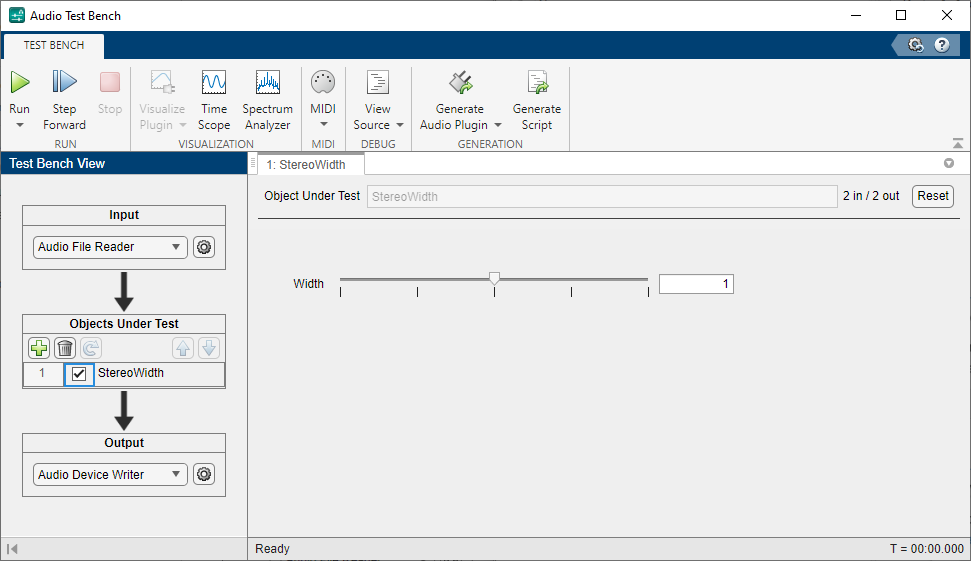

## Validate and Generate a VST Plugin

You can validate a MATLAB® audio plugin and generate a VST plugin from the **Audio Test Bench**. You can also validate and generate the plugin from the command line by using the [validateAudioPlugin](docid:audio_ref#bu1_bv1-1) and [generateAudioPlugin](docid:audio_ref#bu10gt_) functions. Once generated, you can deploy your plugin to a digital audio workstation (DAW).

validateAudioPlugin StereoWidth


Checking plugin class 'StereoWidth'... 

passed.
Generating testbench file 'testbench_StereoWidth.m'... done.
Running testbench... passed.
Generating mex file 'testbench_StereoWidth_mex.mexw64'... done.
Running mex testbench... passed.
Deleting testbench.
Ready to generate audio plugin.



generateAudioPlugin StereoWidth

.......


The VST plugin is saved to your working directory.

*Copyright 2019 The MathWorks, Inc.*